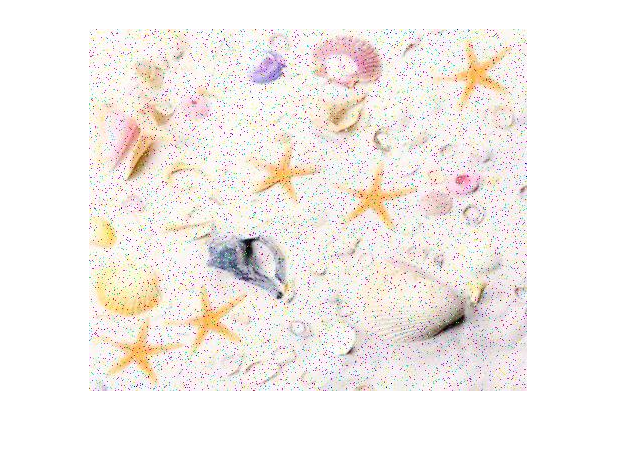

%Original File Comparison --------------------------------
OriginalFile = "./workingImages/starfish.jpg";
OriginalImage = LoadImage(OriginalFile);

%File to compare to
%FileName = "./workingImages/starfish_map3.jpg";
FileName = "./notWorking/seashell_five.jpg"

FileName = "./notWorking/seashell_five.jpg"

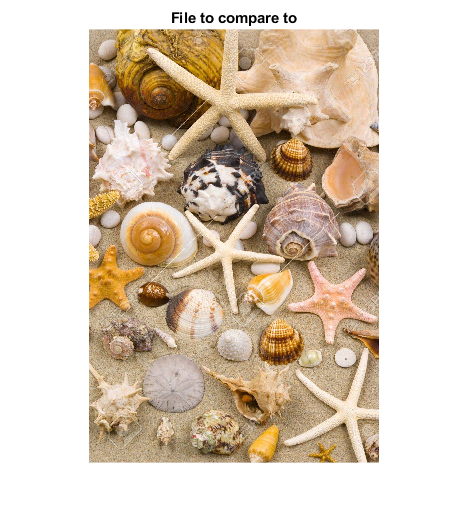

%FileName = "./notWorking/starfish_5.jpg"
Comparison = LoadImage(FileName);

title("File to compare to");

disp("RGB Original Image");

RGB Original Image


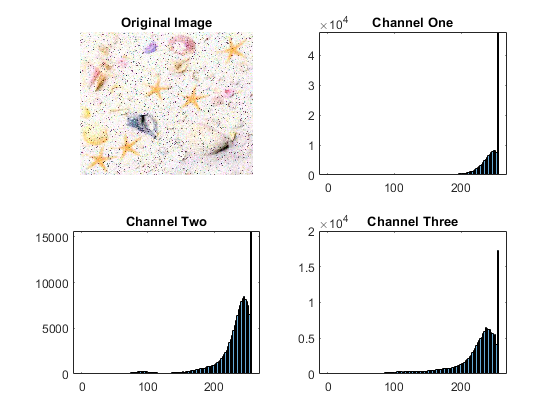

ThreeChannelHistorgram(OriginalImage);

disp("RGB Comparitor");

RGB Comparitor


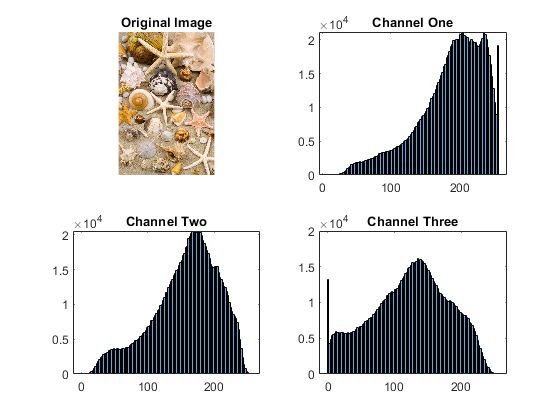

ThreeChannelHistorgram(Comparison);

disp("HSV Original Image");

HSV Original Image


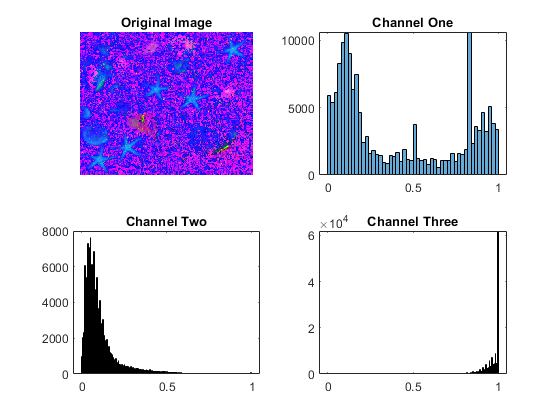

hsvOrignal = rgb2hsv(OriginalImage);
ThreeChannelHistorgram(hsvOrignal);

disp("HSV Comparitor");

HSV Comparitor


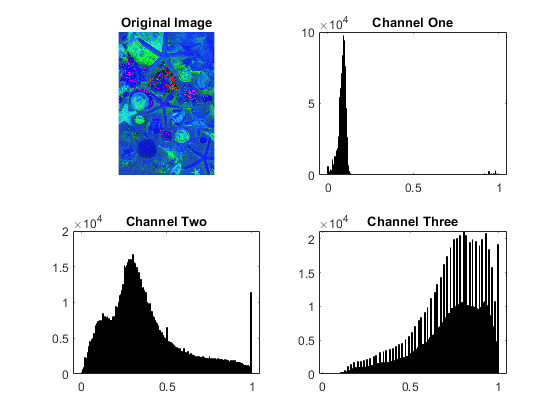

hsvComparitor = rgb2hsv(Comparison);

ThreeChannelHistorgram(hsvComparitor);

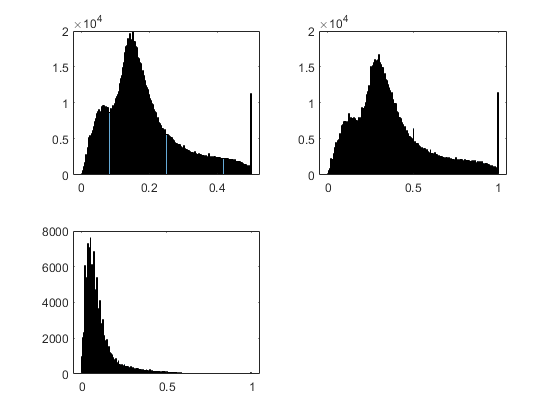


figure
subplot(2,2,1);
histogram(hsvComparitor(:,:,2) * 0.5);
subplot(2,2,2);
histogram(hsvComparitor(:,:,2));
subplot(2,2,3);
histogram(hsvOrignal(:,:,2));


hsvTest = cat(3, (hsvComparitor(:,:,1)), hsvComparitor(:,:,2) * 4, hsvComparitor(:,:,3));
hsvTest = hsv2rgb(hsvTest);
hsvTest = uint8(hsvTest * 255)

hsvTest = 1300×870×3 uint8 array
hsvTest(:,:,1) =

   185   186   186   181   179   185   194   198   196   206   201   179   199   212   187   192   206   192   194   194   178   172   182   188   201   194   199   190   189   185   175   198   201   182   170   192   177   188   187   194   193   178   179   186   182   179   176   166   160   167   177   183   183   178   175   175   186   187   186   182   181   183   183   181   168   183   195   196   189   184   183   183   178   186   185   186   192   188   190   205   203   197   194   194   193   185   183   184   191   204   189   170   174   181   176   165   171   187   180   219   193   188   197   190   187   189   188   175   156   143   139   142   156   164   163   159   157   161   160   151   156   149   154   168   181   192   200   206   202   204   207   211   215   217   220   222   232   237   241   244   246   243   233   222   253   250   244   240   236   232   227   224   230   200   179   172   122    89 

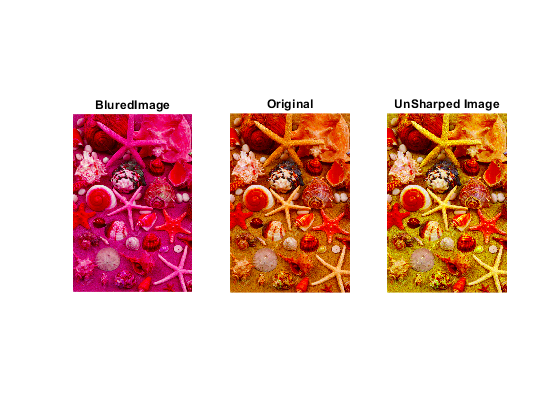

hsvTest = unSharpen(hsvTest, 2, .5);

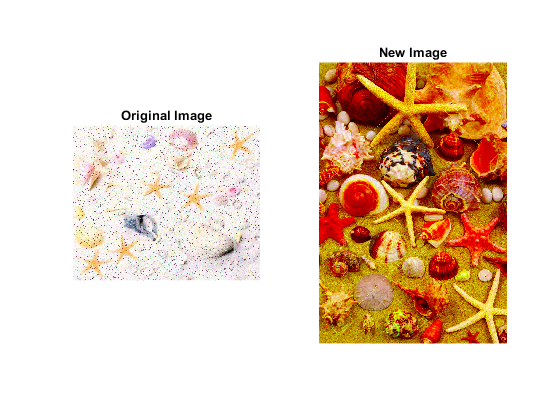



figure
subplot(1,2,1);
imshow(OriginalImage);
title("Original Image");
subplot(1,2,2);
imshow((hsvTest));
title("New Image")

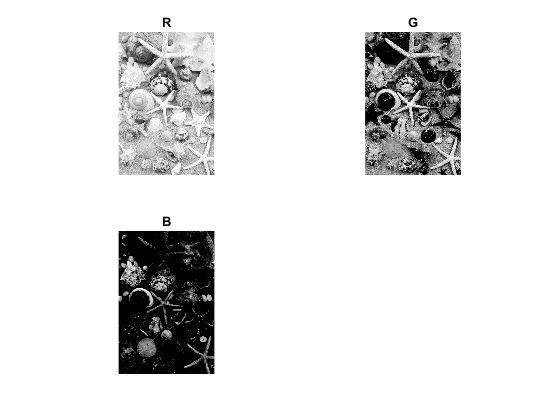

figure
subplot(2,2,1);
imshow(hsvTest(:,:,1));
title("R");
subplot(2,2,2);
imshow(hsvTest(:,:,2));
title("G");
subplot(2,2,3);
imshow(hsvTest(:,:,3));
title("B");

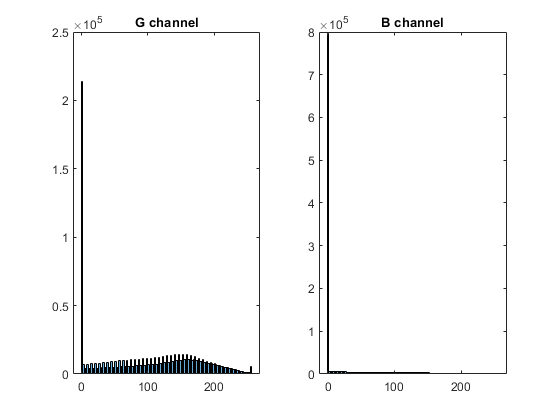

figure
title("Comparining the histograms of each channel");
subplot(1,2,1);
g = histogram(hsvTest(:,:,2)).BinCounts;
histogram(hsvTest(:,:,2));
title("G channel");
subplot(1,2,2);
b = histogram(hsvTest(:,:,3)).BinCounts;
histogram(hsvTest(:,:,3));

title("B channel");

if mean(b) > mean(g)
output = double(hsvTest(:,:,3)) %- double(hsvTest(:,:,3));
else
    output = double(hsvTest(:,:,2))
end

output =    165   167   157   155   161   172   173   178   162   178   175   144   166   188   151   155   165   154   157   159   140   129   140   145   163   152   159   149   149   144   129   185   199   195   173   204   174   189   186   197   199   173   171   184   180   173   161   153   147   152
   179   185   174   162   155   151   147   152   168   168   170   161   179   178   141   168   152   146   140   152   133   135   142   150   163   157   169   168   151   161   150   181   197   194   181   216   187   200   196   211   158   167   189   190   169   170   176   172   124   135
   158   154   142   153   178   191   182   176   174   155   166   179   191   170   134   174   151   146   147   154   145   147   159   159   162   149   180   170   140   158   165   165   181   176   174   210   183   196   189   198   153   177   201   185   156   163   177   157   165   167
   172   167   156   165   176   173   162   161   170   149   166   184   190   176   1


output = uint8(output * 255)

output = 1300×870 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255

output = imbinarize(output);

meanTest = output + 1;
mn = round(mean2(meanTest));
if mn == 2
    disp("Getting the complement")
    output = imcomplement(output);
end

Getting the complement


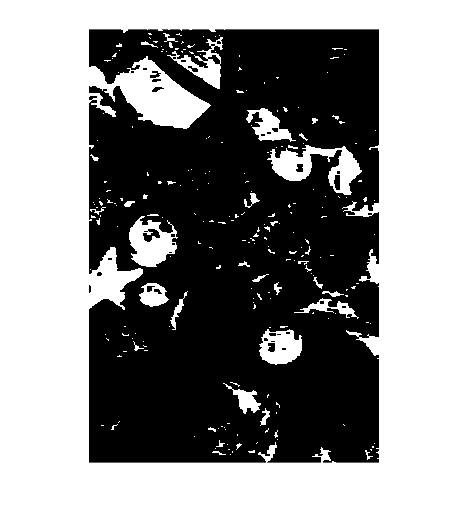

cross = [0,1,0,1,1,1,0,1,0];

circle = strel('disk', 3);

output = imclose(output, cross);
output = imerode(output, circle);


%output = output - bwareaopen(output, 1500)
figure
imshow(output);